%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 比较BESTAnP, Non-app, app 和 Combine_CIO算法
% 在点集中在一个小区域和点比较分散情况。
% 测试 数据 theta的范围 [-scale,scale]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear


% 设置环境变量，允许 OpenMP 运行时重复加载
setenv('KMP_DUPLICATE_LIB_OK', 'TRUE');  %防止报错

% 将此更改为你的脚本目录
py_path = 'C:\Users\Lenovo\Desktop\Matab Code\Experiments\test_numberpoint_influence'; 



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 数据准备
%------------------------------
% 旋转矩阵
R_true=[0.689673028293550	0.423447870703166	0.587403621746887
        0.176155229057263	0.688715772969376	-0.703306419236294
        -0.702367745073895	0.588525687510876	0.400396136119796];
% 平移矢量
t_true = [2;3;4];
t_s_true = -R_true'*t_true;

% 数据大小
num = 100;

scale = 1:10;
phi_max = 10;

for n = 1:length(scale)
    n
    % 生成俯仰角 [-10°, 10°] 转换为弧度
    elevation_angles = deg2rad(-scale(n) + 2*scale(n)*rand(1, num));
   
    % 生成方位角 [-30°, 30°]
    azimuth_angles = deg2rad(-3*scale(n) + 2*3*scale(n)*rand(1, num));
    % 生成距离 [0, 5] 米
    d_true = 6 * rand(1, num);
    
    % 生成 p_s
    p_s(1,:)= (d_true .* cos(elevation_angles) .* cos(azimuth_angles));
    p_s(2,:)= (d_true .* cos(elevation_angles) .* sin(azimuth_angles));
    p_s(3,:)= (d_true .* sin(elevation_angles))';
    
    % 生成 p_si
    p_si(1,:)= d_true .* cos(azimuth_angles);
    p_si(2,:)= d_true .* sin(azimuth_angles);
    
    
    % 生成 p_w
    p_w = R_true*p_s+t_true;

%     M = 1;
    M = 1000;
    
    % Wang's algorithm initial parameters
    error_t_App = 0;
    error_R_App = 0;

    error_t_combine_CIO = 0;
    error_R_combine_CIO = 0;
    

    error_t_Nonapp = 0;
    error_R_Nonapp = 0;

    % Our algorithm initial parameters
    error_t_BESTAnP = 0;
    error_R_BESTAnP = 0;

    for j = 1:M
        %----------------------------------
        stdVar_noise_d = 0.001;
        stdVar_noise_theta = 0.001;
        
        d_noise = d_true + stdVar_noise_d*randn(1, num);
        
        noise_on_theta = stdVar_noise_theta*randn(1, num);
        
        %----------------------------------
        % 生成噪声数据 加在theta上
        tan_theta = tan(azimuth_angles);
        tan_theta_noise = tan_theta + noise_on_theta;
        
        theta_noise_tan= atan(tan_theta_noise);
        cos_theta_noise_tan = cos(theta_noise_tan);
        sin_theta_noise_tan = sin(theta_noise_tan);
        p_si_noise = [d_noise.*cos_theta_noise_tan;d_noise.*sin_theta_noise_tan];

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10


        % Wang's algorithm
        
        [R_app,t_app]=App_Algorithm(p_w,p_si_noise,phi_max,py_path);
        [R_Nonapp,t_Nonapp]=Nonapp_Algorithm(p_w,p_si_noise,phi_max,R_true,py_path);

        [R_combine_CIO,t_combine_CIO] = Combine_CIO(p_w,p_si_noise,phi_max,R_true,py_path);

        % My algorithm
        [R_BESTAnP,t_BESTAnP]=BESTAnP(p_w,p_si_noise);

        %计算估计偏差 R
        s_app = rotm2eul(R_app*R_true','XYZ');
        s_combine_CIO =  rotm2eul(R_combine_CIO*R_true','XYZ');

        s_Nonapp =  rotm2eul(R_Nonapp*R_true','XYZ');

        s_BESTAnP = rotm2eul(R_BESTAnP*R_true','XYZ');

        error_R_App = error_R_App + norm(s_app)^2;

        error_R_combine_CIO = error_R_combine_CIO + norm(s_combine_CIO)^2;
        
        error_R_Nonapp = error_R_Nonapp + norm(s_Nonapp)^2;
      
        error_R_BESTAnP = error_R_BESTAnP + norm(s_BESTAnP)^2;

        %计算估计偏差 t
        error_t_App = error_t_App + norm(t_app-t_true)^2;
        error_t_combine_CIO = error_t_combine_CIO + norm(t_combine_CIO-t_true)^2;

        error_t_Nonapp = error_t_Nonapp + norm(t_Nonapp-t_true)^2;

        error_t_BESTAnP = error_t_BESTAnP + norm(t_BESTAnP-t_true)^2;
    end

    [crlb_R,crlb_t] = Calculate_CRLB(p_w,R_true,t_true,stdVar_noise_d,stdVar_noise_theta);


    CRLB_t_x(n,:) = sqrt(crlb_t);
    CRLB_R_x(n,:) = sqrt(crlb_R);

    % Wang's algorithm
    Error_t_App(n,:) = sqrt(error_t_App/M);
    Error_R_App(n,:) = sqrt(error_R_App/M);

    Error_t_combine_CIO(n,:) = sqrt(error_t_combine_CIO/M);
    Error_R_combine_CIO(n,:) = sqrt(error_R_combine_CIO/M);


    Error_t_Nonapp(n,:) = sqrt(error_t_Nonapp/M);
    Error_R_Nonapp(n,:) = sqrt(error_R_Nonapp/M);



     % my algorithm
    Error_t_BESTAnP(n,:) = sqrt(error_t_BESTAnP/M);
    Error_R_BESTAnP(n,:) = sqrt(error_R_BESTAnP/M);
    
end

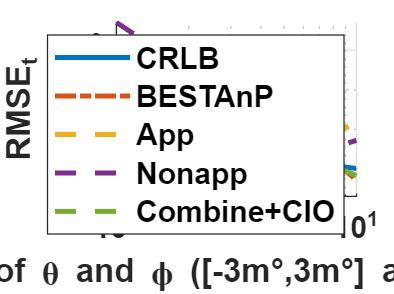

figure
grid on 
hold on;

loglog(scale,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);

loglog(scale,Error_t_BESTAnP,'-.','LineWidth', 2,  'MarkerSize', 5);

loglog(scale,Error_t_App,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(scale,Error_t_Nonapp,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(scale,Error_t_combine_CIO,'--','LineWidth', 2, 'MarkerSize', 5);


legend('CRLB','BESTAnP','App','Nonapp','Combine+CIO','FontSize', 12, 'FontWeight', 'bold');

xlabel('Range of \theta and \phi ([-3m°,3m°] and [-m°,m°])','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_t','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

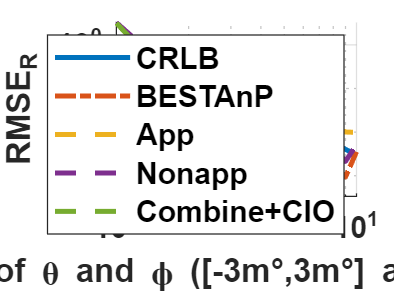

figure
grid on 
hold on;

loglog(scale,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);

loglog(scale,Error_R_BESTAnP,'-.','LineWidth', 2,  'MarkerSize', 5);

loglog(scale,Error_R_App,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(scale,Error_R_Nonapp,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(scale,Error_R_combine_CIO,'--','LineWidth', 2, 'MarkerSize', 5);


legend('CRLB','BESTAnP','App','Nonapp','Combine+CIO','FontSize', 12, 'FontWeight', 'bold');
xlabel('Range of \theta and \phi ([-3m°,3m°] and [-m°,m°])','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_R','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');